# Solution to the *Clustering Corporate Bonds* exercise

## 1. Load data

Load the data in `corpBondData.mat`.

load corpBondData

This file contains a table of simulated data that reflects characteristics of corporate bonds including the type of bond, name, price, coupon rate, maturity date, yield to maturity (YTM), current yield, rating, and whether it is callable or not.

## 2. Select Features to use for Clustering

Extract the variables `Coupon`, `YTM`, `CurrentYield`, and `RatingNum` into a matrix.

bonds = corp{:,{'Coupon','YTM','CurrentYield','RatingNum'}};

## 3. Perform *k*-means clustering

Use *k*-means clustering to cluster the numeric data into three groups using the cosine distance metric.

numClust = 3;
dist_k = 'cosine';
kidx = kmeans(bonds, numClust,'Distance',dist_k);

## 4. Silhouette plot

Create a silhouette plot to evaluate the clustering.

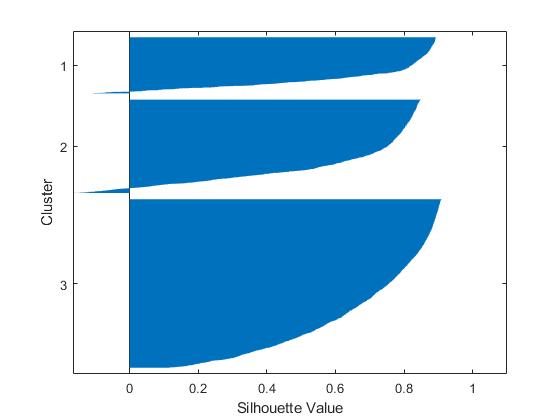

figure
[s,~] = silhouette(bonds,kidx,dist_k);

%title(['Mean silhouette value: ',num2str(mean(s))])

## 5. Visualize results

Create a grouped scatter plot with `Coupon` on the *x*-axis and `YTM` on the *y*-axis, grouped by the results of the *k*-means clustering.

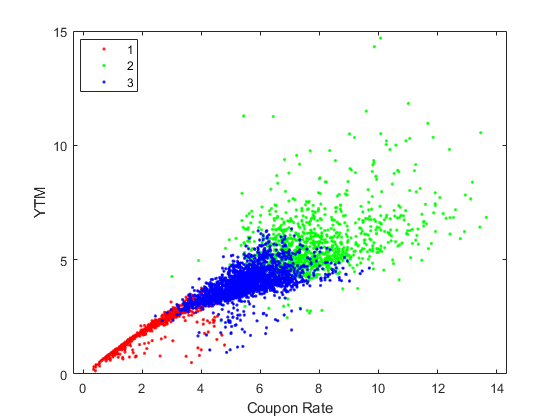

figure
gscatter(corp.Coupon,corp.YTM,kidx)
xlabel('Coupon Rate')
ylabel('YTM')

## Bonus: Optimal number of clusters

 Determine the optimal number of clusters by using the `evalclusters` function.

dist_k = 'cosine';
eva = evalclusters(bonds,'kmeans',...
    'silhouette','KList',2:7,'Distance',dist_k)

eva =   SilhouetteEvaluation with properties:

    NumObservations: 4082
         InspectedK: [2 3 4 5 6 7]
    CriterionValues: [0.6696 0.6685 0.6516 0.5773 0.5566 0.5475]
           OptimalK: 2


## Perform *k*-means clustering

If using three clusters is not optimal, according to the criterion values, repeat steps 3-5 with the optimal number of clusters.

numClust = eva.OptimalK;
kidx = kmeans(bonds,numClust,'Distance',dist_k);

## Silhouette plot

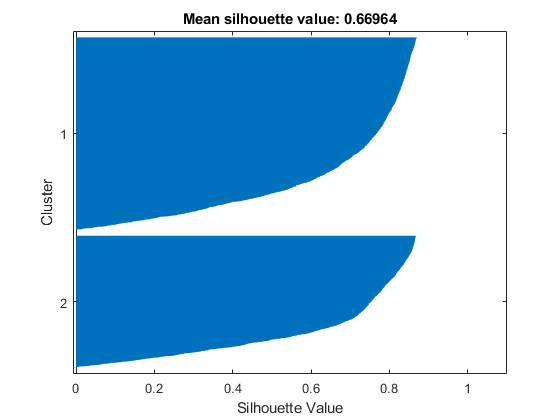

figure
[s,h] = silhouette(bonds,kidx,dist_k);
title(['Mean silhouette value: ',num2str(mean(s))])

## Visualize results

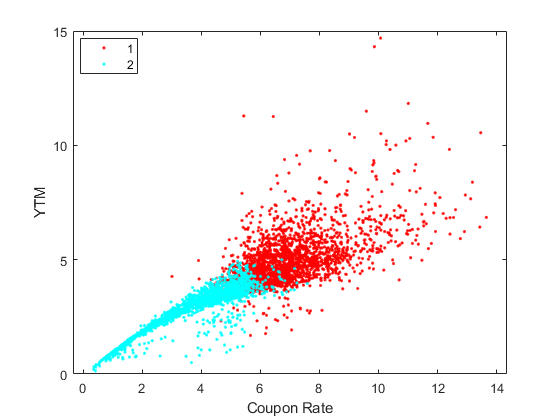

figure
gscatter(corp.Coupon,corp.YTM,kidx)
xlabel('Coupon Rate')
ylabel('YTM')

## Another approach to the bonus

To use a different criterion with the cosine distance metric, make a clustering function and pass that to `evalclusters`:

% clusterfun = @(data,k) kmeans(data,k,'Distance','cosine');
% eva = evalclusters(bonds,clusterfun,'CalinskiHarabasz','KList',2:7)